# FF_DS_AZ_LOOP Dynamic Savings Loop Discrete Distribution

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_ds_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_ds_az_loop.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **F(a,z) discrete probability mass function given policy function solution with discretized savings choices.

- Distribution for Common Choice and States Grid ***Loop***: ff_ds_az_cts_loop

- Distribution for States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***: [**ff_ds_az_cts_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_ds_az_cts_loop.m)

- Distribution for States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Vectorized***: [**ff_ds_az_cts_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_ds_az_cts_vec.m)

## Test FF_DS_AZ_LOOP Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

Elapsed time is 0.159342 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari    min    max
          _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ___    ___

    ap    1     1      2       700     100      7      9855.1    14.079    14.408     1.0234      0     50 

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
             

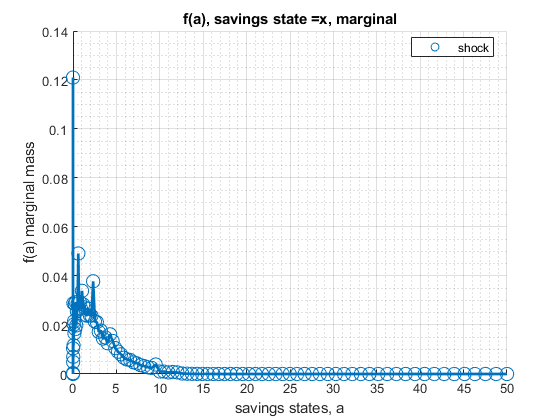

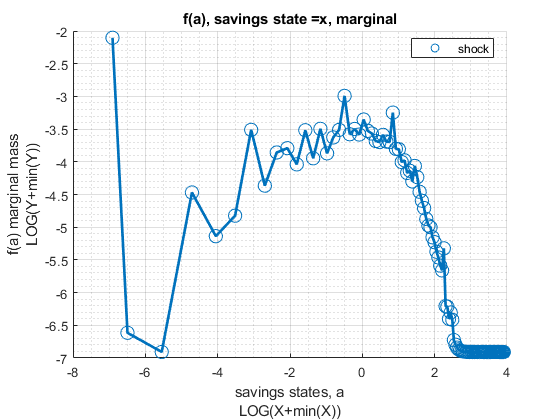

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
% call function
ff_ds_az_loop(mp_params);

## Test FF_DS_AZ_LOOP Speed Tests

Call the function with different a and z grid size, print out speed:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {};
mp_support('bl_show_stats_table') = false;
% A grid 50, shock grid 5:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_ds_az_loop(mp_params, mp_support);

Elapsed time is 0.025627 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 0.066138


% A grid 100, shock grid 7:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
ff_ds_az_loop(mp_params, mp_support);

Elapsed time is 0.155714 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 0.11763


% A grid 200, shock grid 9:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 200;
mp_params('it_z_n') = 9;
ff_ds_az_loop(mp_params, mp_support);

Elapsed time is 0.332056 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 0.32648


## Test FF_DS_AZ_LOOP A grid 100 Shock grid 7

Call the function with different a and z grid size, print out speed:

Elapsed time is 0.144655 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 0.13625


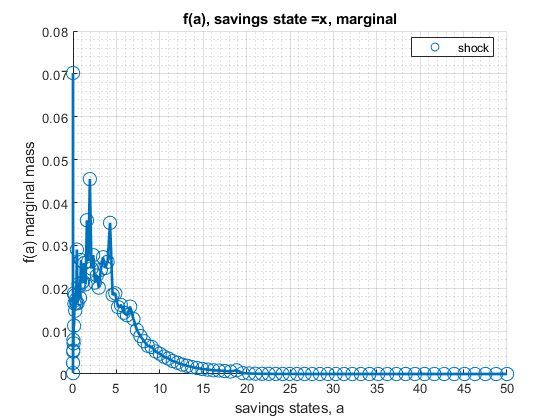

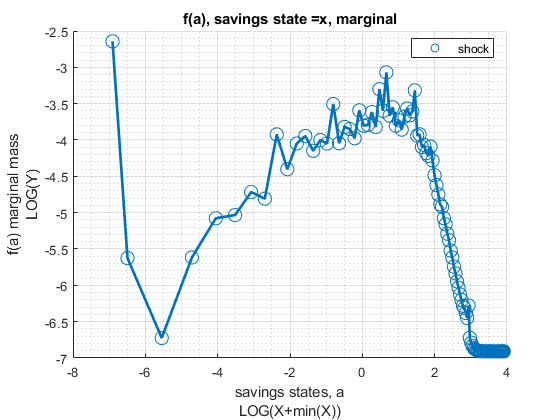

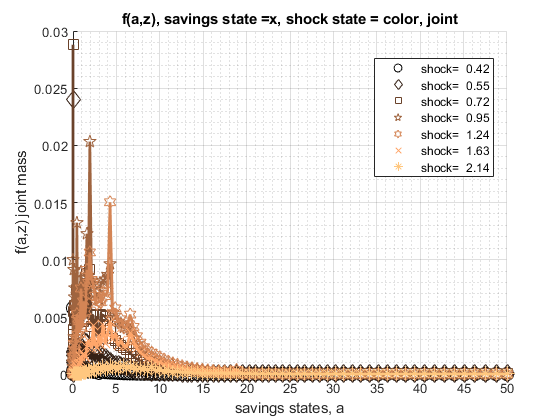

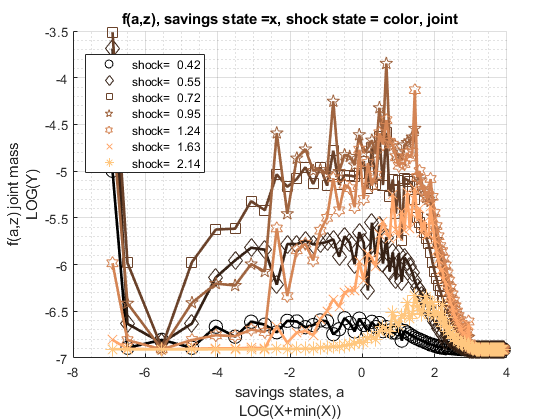

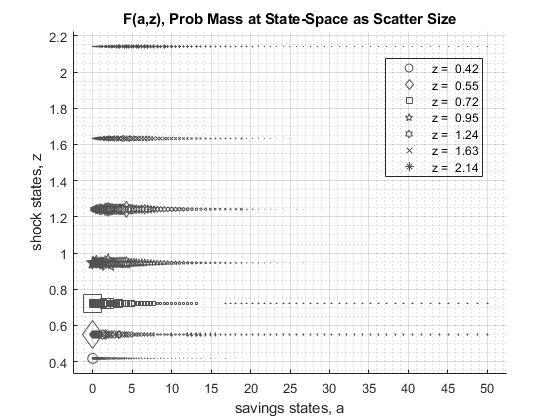

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }        2.7094        6.6576        1.5089        1.5084        4.2183       0.48487 
    {'sd'                }        2.8976        2.0599       0.35843       0.52611        3.2096       0.25477 
    {'coefofvar'         }        1.0694        0.3094       0.23755       0.34879       0.76088       0.52544 
    {'min'               }             0        1.6927       0.58543       0.58543       0.58543             0 
    {'max'               }            50        19.139    

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
ff_ds_az_loop(mp_params, mp_support);

## Test FF_DS_AZ_LOOP A grid 300 Shock Grid 25

Elapsed time is 1.664355 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 1.3793


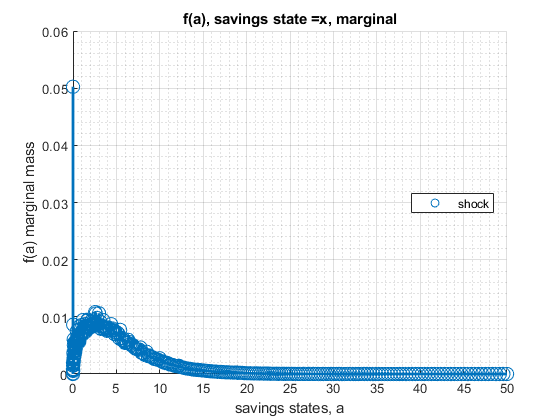

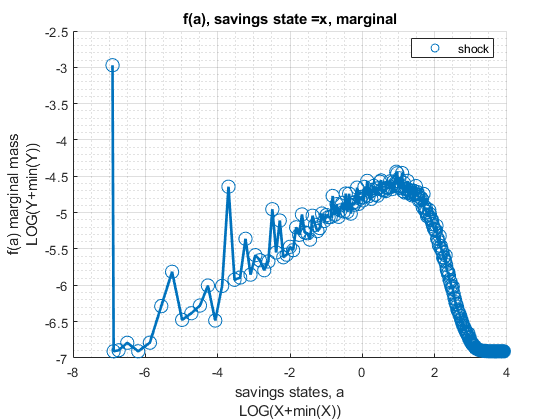

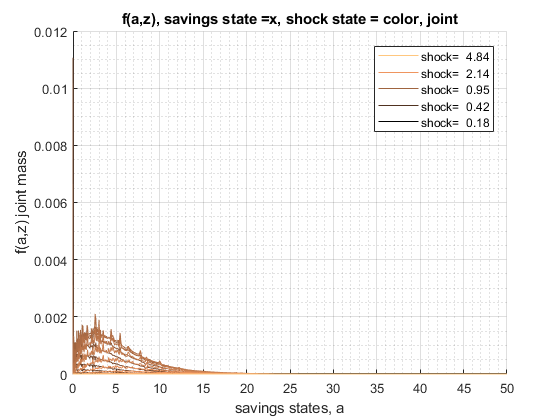

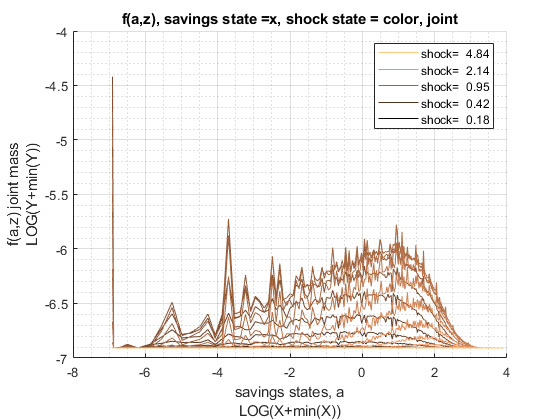

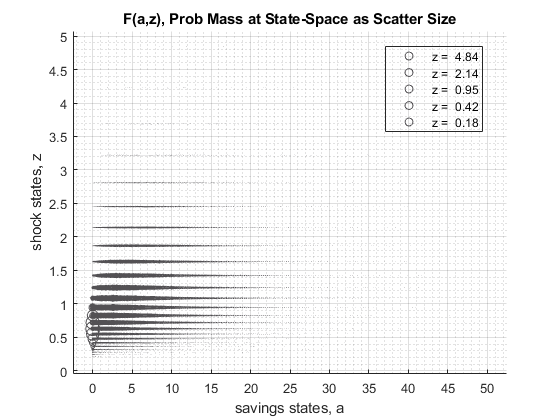

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }        3.1835        6.9106        1.5286        1.5274        4.7121       0.52236 
    {'sd'                }        3.2831         2.152       0.35175       0.53521        3.5973       0.25161 
    {'coefofvar'         }        1.0313       0.31141        0.2301       0.35041       0.76341       0.48168 
    {'min'               }             0       -2.7621       0.25871       0.25871       0.25871             0 
    {'max'               }            50        20.027    

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 300;
mp_params('it_z_n') = 25;
ff_ds_az_loop(mp_params, mp_support);

## Test FF_DS_AZ_LOOP A grid 300 Shock Grid 50

Elapsed time is 4.319877 seconds.
FF_DS_AZ_LOOP finished. Distribution took = 3.0884


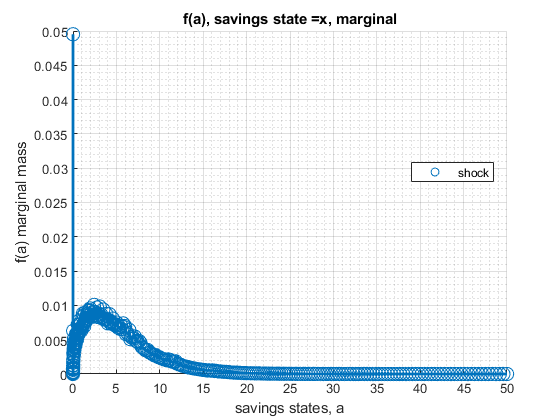

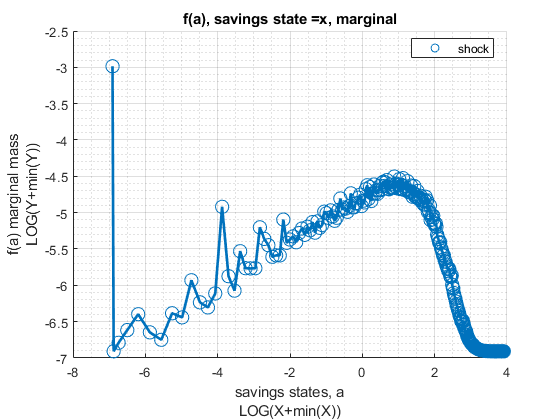

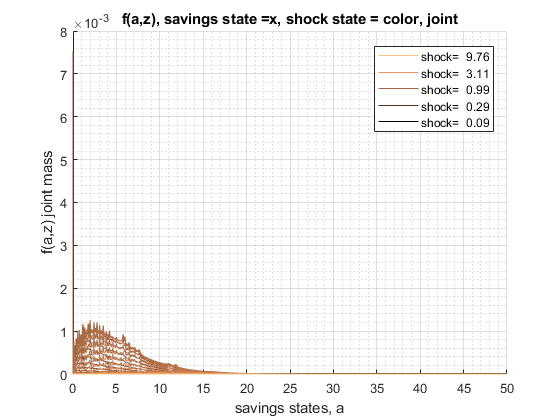

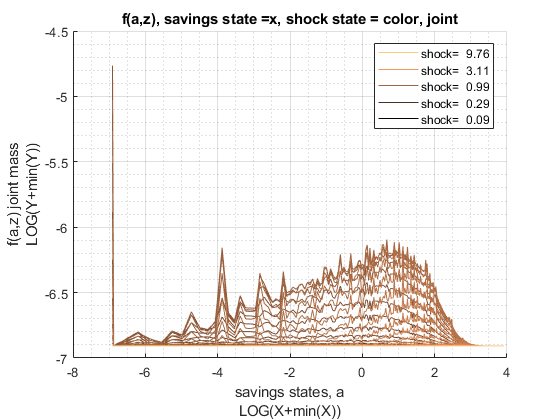

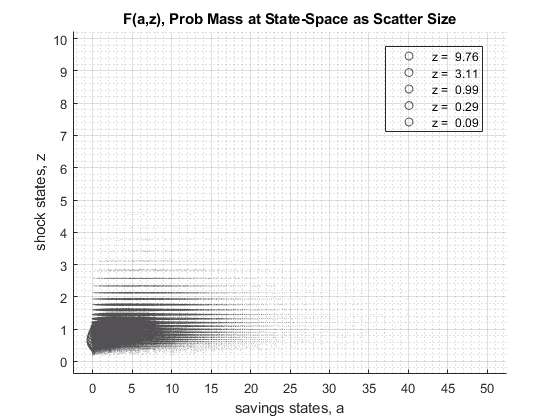

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }          3.26        6.9484        1.5319        1.5305        4.7919       0.52772 
    {'sd'                }        3.3166        2.1606       0.35167        0.5364        3.6315       0.25217 
    {'coefofvar'         }        1.0174       0.31094       0.22956       0.35048       0.75783       0.47785 
    {'min'               }             0       -7.6871       0.12843       0.12843       0.12843             0 
    {'max'               }            50        20.751    

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 300;
mp_params('it_z_n') = 50;
ff_ds_az_loop(mp_params, mp_support);